# Computing  minimal cut sets

## Author: Susan Ghaderi, Luxembourg Centre for Systems Biomedicine 

## Reviewers: Sylvain Arreckx, Laurent Heirendt

## INTRODUCTION

During this tutorial, you will learn how to compute  cutsets for paths/cycles/elementary modes with Berge algorithm [1].

Elementary modes describe a feasible and balanced (steady state) flux distribution through the network, which is minimal with respect to utilized reactions (enzymes). The condition of being ‘minimal’ (elementary, non-decomposable, irreducible) is fundamental and means that removing any reaction in an elementary mode impedes the realization of a non-zero steady-state flux distribution (and therefore of a functionality) by means of the remaining reactions of the elementary mode. Now, assume that we want to prevent the production of metabolite X.  One strategy would be to inactivate (cut) one or several reactions in the network, e.g. by deleting the genes of certain enzymes or by other manipulations resulting in an inhibition of enzyme activity. This leads us to the definition of a cut set: a set of reactions a cut set (with respect to a defined objective reaction) if after the removal of these reactions from the network no feasible balanced flux. In other hands, a cut set for an objective reaction in a metabolic network is a set of reactions whose knockout disables flux through that reaction at steady state. Cut sets represent a particular type of failure mode of a metabolic network and may correspond to novel drug targets.

  The set of all feasible fluxes


$$K=\{ v\in R^n|Sv=0,v \geq 0, v\in Irr \}$$


is a polyhedral cone in $R^n$where $Irr$ is a set of irreversible reaction. A set of reactions $C$ subset of reactions, is a cut set for an objective $j\text{  }$among reactions, if 


$$v_c=0 ~leads~to ~v_j=0~\forall~r \in K.$$


We introduce an interface to software that enables the computation of the .

## MATERIALS

- *Please ensure that the CNA (CellNetAnalyzer) software has been properly installed and initialised. CNA web site (with manual): *[https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) 

## EQUIPMENT SETUP

Requirements for using CellNetAnalyzer are:

- MATLAB Version 7.5 (Release 18) or higher.

- some functions require an LP or (M)ILP solver; CNA supports the optimization toolbox of MATLAB, GLPKMEX, and CPLEX).

- More information can be found on: [https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) where also a how-to tutorial on CellNetAnalyzer is provided.

## PROCEDURE 

*Before you start with these codes, you should initialise CNA software by the following commands*

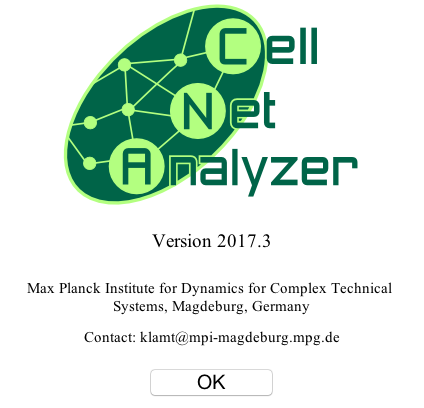

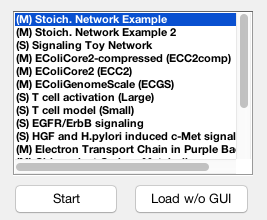

% Add path to Cell Net Analyzer
CNAPath = '~/CellNetAnalyzer';
addpath(genpath(CNAPath));
startcna

## Computing minimal cut set

The mandatory input in minimal cut set code is the set such as paths/cycles/elementary-modes that you are going to compute its minimal cut set. 

% define the model
global CBTDIR
addpath([CBTDIR filesep 'tutorials' filesep 'minimalCutSets'])

load('E.mat')% the set of elementary modes which we are going to compute its minimal cut set.
C = minimalCutSets(E(1,:))

 
Computing minimal cut sets / hypergraph transversal
***************************************************
Found and removed 2 elements not contained in any mode.
 
Number of elements that cannot be deleted due to side constraints : 0
 
Number of admissable cut sets with 1 element : 3
 
0 equivalent elements found and removed
0 remaining elements
 
Ready! Computation time: 0.03 sec
Longest list merge: 0.
Compressed MCS list length: 3.
 
Final result: 3 cut sets.


C =    1   0   0   0   0
   0   1   0   0   0
   0   0   0   0   1


C =    1   0   0   0   0
   0   1   0   0   0
   0   0   0   0   1


C = minimalCutSets(E(2,:))

 
Computing minimal cut sets / hypergraph transversal
***************************************************
Found and removed 2 elements not contained in any mode.
 
Number of elements that cannot be deleted due to side constraints : 0
 
Number of admissable cut sets with 1 element : 3
 
0 equivalent elements found and removed
0 remaining elements
 
Ready! Computation time: 0.02 sec
Longest list merge: 0.
Compressed MCS list length: 3.
 
Final result: 3 cut sets.


C =    0   0   1   0   0
   0   0   0   1   0
   0   0   0   0   1


C =    0   0   1   0   0
   0   0   0   1   0
   0   0   0   0   1


## INPUT

The neccesirelly input for computing minimal cut set of a set is `targets.`

  `targets`:     a binary matrix that row-wise contains the target paths/cycles/elementary modes; a '1' in the i-th row and j-th column in targets indicates participation of element (reaction) j in mode i;

## OPTIONAL INPUTS:

-    `mcsmax`:      maximal size of cutsets to be calculated; must be a value grater 0; Inf means no size limit (default: Inf)

-     `names`:       a char matrix; its rows are names corresponding to the columns of 'targets'; used for diagnostics in preprocessing (default:[]; the matrix is then constructed with 'I1,',I2',....)

-     `sets2save`:   (default: []) struct array with sets of (desired) modes/paths/cycles that should be preserved (not be hit by the   cut sets computed). Should have the following fields

                 * sets2save(k).tabl2save = k-th matrix containing row-wise 'desired' sets (desired paths/cycles/ modes) that should not     be hit by the cut sets to be computed. be saved A '1' in the i-th row and j-th column of sets2save(k) indicates participation of element j in mode i in set k of desired modes. These matrics must have the same number of columns (reactions) as 'targets'.

               * sets2save(k).min2save = specifies the minimum number of desired paths/cycles/modes in sets2save(k).tabl2save that should not be hit by the cut sets computed.

-  `earlycheck`:   whether the test checking for the fulfillment of constraints in sets2save should be caried out during (1) or after (0) computation of cut sets [default: 1; makes only sense in combination with sets2save]

##  OUTPUT:

   `C`:     matrix that contains the (constrained) cutsets row-wise; a '1' means that the reaction/interaction  is part of the cutset, 0 means the element/reaction/interaction is not involved. Each cutset hits all modes stored in "targets" while it does not hit at least

  "sets2save(k).min2save" many modes in "sets2save(k).tabl2save".

## TIMING

Running, the codes are dependent on the size of models may take long from 30 seconds to few hours. But in addition to the time of running you should consider between 60 seconds for start-up CNA software.

## ANTICIPATED RESULTS

The anticipated results is minimal cut set of every set which is as an input.

## REFERENCES

[1] Klamt. S. and Gilles ED. Minimal cut sets in biochemical reaction networks. Bioinformatics. 20, 226–234 (2004).

[2] Berge. C.  Hypergraphs, ser.North holland Mathematical Library. Elsiver Science Publishers B. V. 45, (1989).